### Computational Method in Ordinary Differential Equations

*Dr Jon Shiach, Department of Computing and Mathematics, Manchester Metropolitan University*

# Runge-Kutta Methods

#### Learning outcomes

On successful completion of this page readers will be able to:

- Identify a Runge-Kutta method and express it using a Butcher tableau;

- Distinguish between explicit and implicit Runge-Kutta methods;

- Derive an explicit Runge-Kutta method using the order conditions;

- Apply explicit Runge-Kutta methods to solve an initial value problem.

[Runge-Kutta methods](https://en.wikipedia.org/wiki/Runge%E2%80%93Kutta_methods) are a family of numerical methods for solving a first-order [Ordinary Differential Equation](https://en.wikipedia.org/wiki/Ordinary_differential_equation) (ODE). The general form of a Runge-Kutta method for solving the ODE $y'=f(t, y)$ is


$$\begin{array}{ll}
y_{n+1} = y_n + h \sum_{i=1}^s b_i k_i, &  (1) \\ 
k_i = f(t_n + c_ih, y_n + h\sum_{j=1}^s a_{ij} k_j). \qquad &(2)
\end{array}$$


where $t_n$ is some value of the independent variable $t$, $y_n=y(t_n)$ is the value of the function $y$ when $t=t_n$, $h=t_{n+1}-t_n$ is the **step length** between two successive values of $t$, $k_i$ are intermediate **stage values** and $s$ is the number of stages of the method. Runge-Methods are called **single step methods** because they update the solution for the next step $y_{n+1}$ using information from the single step $y_n$. The other type of method for solving ODEs are [**multistep methods**](https://en.wikipedia.org/wiki/Linear_multistep_method) that calculate $y_{n+1}$ using information from multiple steps $y_n, y_{n-1}, y_{n-2}, \ldots$

### Butcher tableau

A commond method used to express a Runge-Kutta method is to use a **Butcher tableau. **Expanding the summations of the general form of a Runge-Kutta method


$$y_{n+1} = y + h(b_1k_1 + b_2k_2 + \cdots + b_sk_s), \\
\quad k_1 = f(t_1 + c_1h, y_n + h(a_{11}k_1 + a_{12}k_2 + \cdots + a_{1s}k_s), \\
\quad k_2 = f(t_2 + c_2h, y_n + h(a_{21}k_1 + a_{22}k_2 + \cdots + a_{2s}k_s), \\
\quad \vdots \\
\quad k_s = f(t_s + c_sh, y_n + h(a_{s1}k_1 + a_{s2}k_s + \cdots +a_{ss}k_s).$$


It is the values of the coefficients $a_{ij}$, $b_i$ and $_ci$ the define a particular Runge-Kutta method and these values are arranged in tabular form as follows


$$\begin{array}{c|cccc} 
c_1 & a_{11} & a_{12} & \cdots & a_{1s} \\ 
c_2 & a_{21} & a_{22} & \cdots & a_{2s} \\ 
\vdots & \vdots & \vdots & \ddots & \vdots \\ 
c_s & a_{s1} & a_{s2} & \cdots & a_{ss}  \\
 & b_1 & b_2 & \cdots & b_s \end{array}$$


## Explicit and implicit Runge-Kutta methods

The stage values of a general Runge-Kutta method are


$$k_1 = f(t_n + c_1h, y_n + h(a_{11}k_1 + a_{12}k_2 + \cdots + a_{1s}k_s), \\
k_2 = f(t_n + c_2h, y_n + h(a_{21}k_1 + a_{22}k_2 + \cdots + a_{2s}k_s), \\
\vdots \\
k_s = f(t_n + c_sh, y_n + h(a_{s1}k_1 + a_{s2}k_s + \cdots + a_{ss}k_s).$$


Here the equation for calculating the value of $k_1$ includes $k_1$ on the right-hand side and similar for $k_2, k_3, \ldots, k_s$. These are examples of **implicit** equations and Runge-Kutta methods where the stage values are expressed using implicit equations are known as **Implicit Runge-Kutta** (IRK) methods. To calculate the solution of the stage values of an IRK method involves solving a system of equations which is computationally expensive.

If the summation in equation (2) is altered so the upper limit to the sum is $i-1$, i.e.,


$$k_i = f(t_n + c_1h, y_n + h \sum_{j=1}^{i-1}a_{ij}k_j),$$


and let $c_1=0$ then we have the following euqations for calculating the stage values


$$k_1 = f(t_n, y_n), \\
k_2 = f(t_n + c_2h, y_n + ha_{21}k_1), \\
k_3 = f(t_n + c_3h, y_n + h(a_{31}k_1 + a_{32}k_2), \\
\vdots \\
k_s = f(t_n + c_sh, y_n + h(a_{s1}k_1 + a_{s2}k_s + \cdots + a_{s,s-1}k_{s-1}).$$


These stages values are **explicit** equations where the subject of the equation does not appear on the right-hand side. Runge-Kutta methods where the stages values are calculated using explicit equations are known as **Explicit Runge Kutta** (ERK) methods. Note that we can calculate the stage values in order, i.e., $k_1$ can be calculated using $t_n$ and $y_n$; $k_2$ can be calculated using $t_n$, $y_n$ and $k_1$; $k_3$ can be calculated using $t_n$, $y_n$, $k_1$ and $k_2$ and so on. This means that ERK methods as more computationally efficient than IRK methods, however in certain situations ERK methods cannot be used and we must then use IRK methods.

### Butcher tableau for explicit and implicit Runge-Kutta methods

ERK and IRK methods can be easily distinguished looking at the Butcher tableau. The $A$ matrix in the top right region of a Butcher tableau for an ERK method (left) is lower-triangular whereas for an IRK method (right) the main-diagonal and upper triangular elements are non-zero.


$$\pmatrix{ 
0 \cr 
a_{21} \cr 
a_{31} & a_{32} \cr
\vdots & \vdots & \ddots \cr
a_{s1} & a_{s2} & \cdots & a_{s,s-1} }
\qquad \qquad
\pmatrix{a_{11} & a_{12} & a_{13} & \cdots & a_{1s} \cr
a_{21} & a_{22} & a_{23} & \cdots & a_{2s} \cr
a_{31} & a_{32} & a_{33} & \cdots & a_{3s} \cr
\vdots & \vdots & \vdots & \ddots & \vdots \cr
a_{s1} & a_{s2} & a_{s3} & \cdots & a_{ss}}$$


## Derivation of a second-order explicit Runge-Kutta method

A Runge-Kutta method is derived by comparing the [Taylor series](https://en.wikipedia.org/wiki/Taylor_series) of the general Runge-Kutta method and ensuring the coefficients $a_{ij$, $b_i$ and $c_i$ match those of the Taylor series expansion of the ODE $y'=f(t, y)$.

the second-order Taylor series expansion of $y(t+h)$ is


$$y_{n+1} = y + hy' + \frac{h^2}{2} y''$$


Since $y'=f(t, y)$ and applying the [chain rule](https://en.wikipedia.org/wiki/Chain_rule) to differentiate $y'$ we have

$y'' = f_t(t, y) + f_y(t, y)f(t, y)$,

then the Taylor series becomes


$$y_{n+1} = y+h(t, y) + \frac{h^2}{2}(f_t(t, y) + f_y(t, y)f(t, y)) \\
\quad \,\,\,\,\,= y + \frac{h}{2}f(t, y) + \frac{h}{2}(f(t, y) + hf_t(t, y) + hf_y(t, y)f(t,y)). \qquad \qquad (3)$$


The general form of a second-order Runge-Kutta method is


$$y_{n+1} = y_n + hb_1(f_n,y_n) + hb_2f(t+c_2h, y+ha_{21}f(t_n,y_n)), \qquad \qquad (4)$$


The first-order bivariate Taylor series expansion of $f(t_n+c_2h, y_n + ha_{21}f(t_n, y_n))$ is


$$f(t_n+c_2h, y_n + ha_{21}f(t_n,y_n)) = f(t_n,y_n) + hc_2f_t(t_n,y_n)+ha_{21}f(t_n,y_n)f_y(t_n,y_n)$$


whichi is substituted into equation (4) to give


$$y_{n+1} = y_n + hb_1f(t_n,y_n) + hb_2(f(t_n,y_n)+hc_2f_t(t_n,y_n) + ha_{21}f(t_n,y_n)f_y(t_n,y_n)). \qquad \qquad (5)$$


Equating (3) and (5) we see that


$$b_1 + b_2 = 1, \\
\quad \,c_2b_2 = \frac{1}{2}, \\
\,\,\,\,\,\, a_{21}b_2 = \frac{1}{2}$$


Here we have a system of 3 equations expressed in the 4 unknowns $a_{21}$, $b_1$, $b_2$, $c_2$. These equations are known as the **order conditions** for a second-order Runge-Kutta method. To derive a second-order ERK method we choose a value for one of these coefficients and solve for the others.

#### Example 1

Derive an ERK method where $c_2=1$.

The code below uses the `solve` command to solve the order conditions for a second-order ERK method.

% Initialise symbolic variables
syms b1 b2 c2 a21
c2 = 1;

% Define order conditions
eqn1 = b1 + b2 == 1;
eqn2 = c2 * b2 == 1/2;
eqn3 = a21 *b2 == 1/2;

[a21, b1, b2] = solve(eqn1, eqn2, eqn3)

$$a21 = 1$$

$$b1 = \frac{1}{2}$$

$$b2 = \frac{1}{2}$$

So $a_{21}=1$, $b_1=\frac{1}{2}$ and $b_2=\frac{1}{2}$ so this second-order ERK method is


$$y_{n+1} = y_n + \frac{h}{2}(k_1 + k_2), \\
\quad k_1 = f(t_n, y_n), \\
\quad k_2 = f(t_n+h, y_n + hk_1).$$


## Use of expliticit Runge-Kutta methods to solve initial value problems

Runge-Kutta methods are used to solve [Initial Value Problems](https://en.wikipedia.org/wiki/Initial_value_problem) (IVP) of the form


$$y'=f(t, y), \qquad t\in [t_{\min}, t_{\max}], \qquad y(t_{\min})=y_0,$$


where $y'=f(t, y)$ is a first-order ODE defined over the domain $t\in [t_{\min},t_{\max}]$ and the initial solution $y(t_{\min})$ is the known value $y_0$.

To apply the an ERK method to solve an IVP we calculate the stage values $k_1, k_2, \ldots, k_s$ using the known values of $t_n$, $y_n$ and the step length $h$ substituted into the ODE function $f(t, y)$. Then the solution over one step $t_{n+1} = t_n + h$ and $y_{n+1} = y(t_{n+1})$ is then calculated using $k_1, k_2, \ldots, k_s$.

#### Example 2

Calculate the first two steps of the RK2 method to solve the following IVP


$$y' = \sin^2(t)y, \qquad t\in[0, 5], \qquad y(0)=1.$$


using a step length of $h=0.5$.

Step 1: $t_0=0$ and $y_0=1$


$$k_1 = \sin^2(t_0)y_0 = \sin^2(0)(1) = 0, \\
k_2 = \sin^2(t_0+h)(y_0+hk_1) = \sin^2(0+0.5)(1+0.5(0)) = 0.2298, \\
y_1 = y_0+\frac{h}{2}(k_1 + k_2) = 1 + \frac{0.5}{2}(0 + 0.2298) = 1.0575, \\
t_1 = t_0 + h = 0 + 0.5 = 0.5.$$


Step 2: $t_1=0.5$ and $y_1=1.0575$


$$k_1 = \sin^2(t_1)y_1 = \sin^2(0.5)(1.0575) = 0.2431, \\
k_2 = \sin^2(t_1+h)(y_1+hk_1) = \sin^2(0.5+0.5)(1.0575 + 0.5(0.2431)) = 0.8348, \\
y_2 = y_1 + \frac{h}{2}(k_1+k_2) = 1.0575 + \frac{0.5}{2}(0.2431 + 0.8349) = 1.3269.$$


#### Example 3

Calculate the solution of the IVP from example 1 over the whole domain $t\in[0,5]$ using the Euler method with a step length of $h=0.5$ and compare it to the exact solution given by

$y=e^{(t-\sin(t)\cos(t))/2}$.

The function called rk2 below is defined in the Functions section at the bottom of this page calculates the solution to an IVP using the RK2 method. The input arguments are `f` is the name of the funcion the defines the ODE, `tspan` is a two-element array containing the lower and upper bounds of the $t$ domain, `y0` is the initial value of $y$ at the lower bound and `h` is the step length.

The program below invokes the RK2 method to solve this IVP.

clear

% Define ODE function
f = @(t, y) sin(t)^2 * y;

% Define exact solution
exact = @(t) exp(0.5 * (t - sin(t) .* cos(t)));

% Define IVP parameters
tspan = [ 0, 5 ];
y0 = 1;
h = 0.5;

% Invoke RK2 method to solve IVP
[t, y] = rk2(f, tspan, y0, h);

% Output solution table
table = sprintf(' t     RK2     Exact \n--------------------\n');
for n = 1 : length(t)
    table = [table , sprintf('%3.2f %7.4f %7.4f\n', t(n), y(n), exact(t(n)))];
end
fprintf(table)

 t     RK2     Exact 
--------------------
0.00  1.0000  1.0000
0.50  1.0575  1.0404
1.00  1.3269  1.3135
1.50  2.0088  2.0436
2.00  3.1302  3.2845
2.50  4.1734  4.4359
3.00  4.5716  4.8059
3.50  4.7364  4.8830
4.00  5.6020  5.7699
4.50  8.1257  8.5589
5.00 12.8273 13.9573


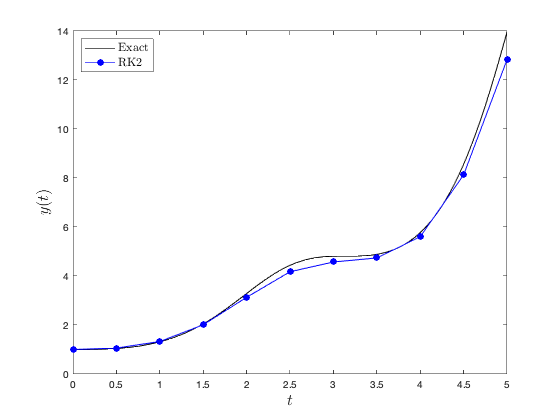

% Plot solutions
t1 = linspace(tspan(1), tspan(2), 100);
plot(t1, exact(t1), 'k-')
hold on
plot(t, y, 'bo-', 'markerfacecolor', 'blue')
hold off

xlabel('$t$', 'fontsize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
leg = legend('Exact', 'RK2');
set(leg, 'Location', 'Northwest', 'FontSize', 12, 'Interpreter', 'latex')

Here we can see that the RK2 solution follows the approximate shape of the exact solution, however, there are still noticeable errors in the numerical solution. Use of a higher order ERK would improve the accuracy of the numerical results.

## Derivation of a fourth-order explicit Runge-Kutta method

The order conditions for a fourth-order ERK method are


$$\begin{array}{rl}
b_1 + b_2 + b_3 + b_4 =& 1, \\
b_2c_2 + b_3c_3 + b_4c_4 =& \frac{1}{2}, \\
b_2c_2^2 + b_3c_3^2 + b_4c_4^2 =& \frac{1}{3}, \\
b_2c_2^3 + b_3c_3^3 + b_4c_4^3 =& \frac{1}{4}, \\
b_3c_3a_{32}c_2 + b_4c_4(a_{42}c_2 + a_{43}c_3) =& \frac{1}{8}, \\
b_3a_{32} + b_4a_{42} =& b_2(1 - c_2), \\
b_4a_{43} =& b_3(1 - c_3), \\
0 =& b_4(1 - c_4).
\end{array}$$


A feature of Runge-Kutta methods is the **row sum condition** that states


$$c_i = \sum_{j=1}^s a_{ij},$$


i.e., the value of $c_i$ is equal to the sum of row $i$ of the matrix $A$. Therefore the values of $a_{21}$, $a_{31}$ and $a_{41}$ are


$$c_2 = a_{21}, \\ c_3 = a_{31} + a_{32}, \\ c_4 = a_{41} + a_{42}  + a_{43}.$$


To solve for the unknowns we choose 4 values from $b_1$, $b_2$, $b_3$, $b_4$, $c_2$, $c_3$, $c_4$ and solve the order conditions for the remaining unknowns.

#### Example 4

Derive a fourth-order Runge-Kutta method where $c_2=c_3=\frac{1}{2}$, $c_4=1$ and $b_2=\frac{1}{3}$.

The code below defines and solves the order conditions and row sum conditions for a fourth-order ERK method.

% Initialise symbolic variables
syms a21 a31 a32 a41 a42 a43 b1 b2 b3 b4 c2 c3 c4
c2 = 1/2;
c3 = 1/2;
c4 = 1;
b2 = 1/3;

% Define order conditions
eqn1 = b1 + b2 + b3 + b4 == 1;
eqn2 = b2 * c2 + b3 * c3 + b4 * c4 == 1/2;
eqn3 = b2 * c2^2 + b3 * c3^2 + b4 * c4^2 == 1/3;
eqn4 = b2 * c2^3 + b3 * c3^3 + b4 * c4^3 == 1/4;
eqn5 = b3 * c3 * a32 * c2 + b4 * c4 * (a42 * c2 + a43 * c3) == 1/8;
eqn6 = b3 * a32 + b4 * a42 == b2 * (1 - c2);
eqn7 = b4 * a43 == b3 * (1 - c3);
eqn8 = 0 == b4 * (1 - c4);
eqn9 = c2 == a21;
eqn10 = c3 == a31 + a32;
eqn11 = c4 == a41 + a42 + a43;

% Solver order conditions
[a21, a31, a32, a41, a42, a43, b1, b3, b4] ...
    = solve(eqn1, eqn2, eqn3, eqn4, eqn5, eqn6, eqn7, eqn8, eqn9, eqn10, eqn11)

$$a21 = \frac{1}{2}$$

$$a31 = 0$$

$$a32 = \frac{1}{2}$$

$$a41 = 0$$

$$a42 = 0$$

$$a43 = 1$$

$$b1 = \frac{1}{6}$$

$$b3 = \frac{1}{3}$$

$$b4 = \frac{1}{6}$$

So $a_{21}=\frac{1}{2}$, $a_{31}=0$, $a_{32}=\frac{1}{2}$, $a_{41}=0$, $a_{42}=0$, $a_{43}=1$, $b_1=\frac{1}{6}$, $b_3=\frac{1}{3}$ and $b_4= \frac{1}{6}$ so the method is


$$y_{n+1} = y_n + \frac{h}{6}(k_1 + 2k_2 + 2k_3 + k_4), \\
\quad k_1 = f(t_n,y_n), \\
\quad k_2 = f(t_n + \frac{1}{2}h, y_n + \frac{1}{2}hk_1), \\
\quad k_3 = f(t_n + \frac{1}{2}h, y_n + \frac{1}{2}hk_2), \\
\quad k_4 = f(t_n + h, y_n + hk_3),$$


or as a Butcher tableau


$$\begin{array}{c|cccc}
0 \\
\frac{1}{2} & \frac{1}{2} \\
\frac{1}{2} & 0 & \frac{1}{2} \\ 
1 & 0 & 0 & 1 \\
& \frac{1}{6} & \frac{1}{3} & \frac{1}{3} & \frac{1}{6}
\end{array}$$


This fourth-order ERK is often referred to as *the* Runge-Kutta method or RK4 for short.

#### Example 5

Calculate the first two steps of the RK4 method to calculate the solution of the IVP in example 2 using a step length of $h=0.5$.


$$y'=\sin^2(t)y, \qquad t\in[0, 5], \qquad y(0)=1.$$


Step 1: $t_0=0$ and $y_0=1$


$$\begin{array}{rl}
k_1 &= \sin^2(t_0)y_0  = 1 \sin^2(0) = 0, \\
k_2 &= \sin^2(t_0 + \frac{1}{2} h)(y_0 + \frac{1}{2} h k_1)  = \sin^2(0 + \frac{1}{2} (0.5))(1 + \frac{1}{2} (0.5))  = 0.0612, \\
k_3 &= \sin^2(t_0 + \frac{1}{2} h)(y_0 + \frac{1}{2} h k_2) = \sin^2(0 + \frac{1}{2}(0.5))(1 + \frac{1}{2} (0.5) (0.0612)) = 0.0631, \\
k_4 &= \sin^2(t_0 + h)(y_0 + h k_3) = \sin^2(0 + 0.5)(1 + 0.5 (0.0621)) = 0.2443, \\
y_1 &= y_0 + \frac{h}{6}(k_1 + 2k_2 + 2k_3 + k_4) = 1 + \frac{0.5}{6}(0 + 2(0.0612) + 2(0.0621) + 0.2370) = 1.0411, \\
t_1 &= t_0 + h = 0 + 0.5 = 0.5.
\end{array}$$


Step 2: $t_1=0.5$ and $y_1=1.0411$


$$\begin{array}{rl}
k_1 &= \sin^2(t_1)y_1 = 1.0411 \sin^2(0.5) = 0.2393, \\
    k_2 &= \sin^2(t_1 + \frac{1}{2}h)(y_1 + \frac{1}{2}hk_1) = \sin^2(0.5 + \frac{1}{2}(0.5))(1.0411 + \frac{1}{2}(0.5)(0.2393)) = 0.5393, \\
    k_3 &= \sin^2(t_1 + \frac{1}{2}h)(y_1 + \frac{1}{2}hk_2) = \sin^2(0.5 + \frac{1}{2}(0.5))(1.0411 + \frac{1}{2}(0.5)(0.5393)) = 0.6090, \\
    k_4 &= \sin^2(t_1 + h)(y_1 + hk_3) = \sin^2(0.5 + 0.5)(1.0411 + (0.5)(0.6090)) = 1.1684, \\
    y_2 &= y_1 + \frac{h}{6}(k_1 + 2k_2 + 2k_3 + k_4) = 1.0411 + \frac{0.5}{6}(0.2393 + 2(0.5393) + 2(0.6090) + 1.1684) = 1.3498, \\
    t_2 &= t_1 + h = 0.5 + 0.5 = 1.0.
\end{array}$$


#### Example 6

Calculate the solution of the IVP from example 2 over the domain $t\in[0,5]$ using the RK4 method with a step length of $h=0.5$.

The function called rk4 below is defined in the Functions section at the bottom of this page calculates the solution to an IVP using the RK4 method using the same input arguments as the rk2 function defined earlier.

The program below invokes the RK4 method to solve the previously defined IVP.

% Invoke RK4 method to solve IVP
[t, y] = rk4(f, tspan, y0, h);

% Output solution table
table = sprintf(' t     RK4     Exact \n--------------------\n');
for n = 1 : length(t)
    table = [table , sprintf('%3.2f %7.4f %7.4f\n', t(n), y(n), exact(t(n)))];
end
fprintf(table)

 t     RK4     Exact 
--------------------
0.00  1.0000  1.0000
0.50  1.0403  1.0404
1.00  1.3133  1.3135
1.50  2.0430  2.0436
2.00  3.2830  3.2845
2.50  4.4338  4.4359
3.00  4.8032  4.8059
3.50  4.8795  4.8830
4.00  5.7656  5.7699
4.50  8.5517  8.5589
5.00 13.9431 13.9573


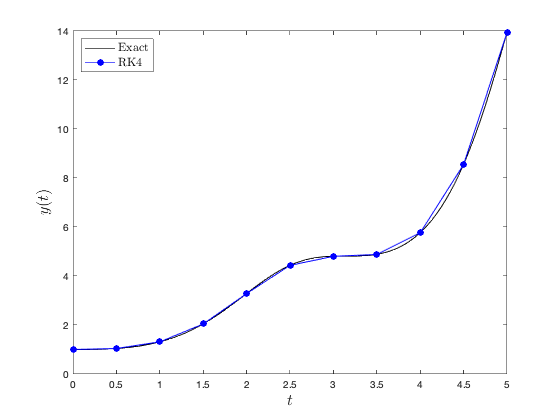

% Plot solutions
t1 = linspace(tspan(1), tspan(2), 100);
plot(t1, exact(t1), 'k-')
hold on
plot(t, y, 'bo-', 'markerfacecolor', 'blue')
hold off

xlabel('$t$', 'fontsize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
leg = legend('Exact', 'RK4');
set(leg, 'Location', 'Northwest', 'FontSize', 12, 'Interpreter', 'latex')

The solution computed by the RK4 method shows very good agreement with the exact solutions. Whilst it is possible to derive higher-order Runge-Kutta methods, in practice the increased accuracy you get is not worth the additional computational cost. The RK4 method is considered the default ODE solver.

## Summary 

- Runge-Kutta methods are single step methods that use intermediate stage values to advance the solution over a small step of length $h$ using known values of $t_n$ and $y_n$ to calculate $y_{n+1}= y(t_n+h)$.

- Runge-Kutta methods are commonly expressed in tabular form called a Butcher tableau.

- There are two types of Runge-Kutta methods: explicit and implicit.

- The coefficients of a Runge-Kutta methods are chosen to satisfy the order conditions which are derived by comparing the Taylor series expansion to the general form of the Runge-Kutta method to the equivalent Taylor series expandion of the first-order ODE $y'=f(t,y)$.

## Exercises

1. Write the following Runge-Kutta method in a Butcher tableau.


$$y_{n+1} = y_n + \frac{h}{6}(k_1 + 4k_3 + k_4), \\
\quad k_1 = f(t_n, y_n), \\
\quad k_2 = f(t_n + \frac{1}{4}h, y_n + \frac{1}{4}hk_1), \\
\quad k_3 = f(t_n + \frac{1}{2}h, y_n + \frac{1}{2}hk_2), \\
\quad k_4 = f(t_n + h, y_n + h(k_1 - 2k_2 + 2k_3)).$$


2. Write out the equations for the following Runge-Kutta method.


$$\begin{array}{c|cccc}
0 & \\
\frac{1}{4} & \frac{1}{4} \\
\frac{1}{2} & -\frac{1}{2} & 1 \\
1 & \frac{1}{4} & 0 & \frac{3}{4} \\
& 0 & \frac{4}{9} & \frac{1}{3} & \frac{2}{9}
\end{array}$$


3. Derive an explicit second-order Runge-Kutta method such that $b_1 = \frac{1}{3}$. Express your solution as a Butcher tableau.

4. Derive an explicit fourth-order Runge-Kutta method such that $b_1=0$ and $c_2=\frac{1}{5}$. Write your answer in the form of a Butcher tableau.

5. Using pen and a calculator and working to 4 decimal places, apply your Runge-Kutta method derived in question 3 to solve the following IVP using a step length of $h=0.4$


$$y'=ty, \qquad t\in[0, 2], \qquad y(0)=1.$$


6. Repeat question 5 using the RK4 method (the RK4 method is derived in example 4).

7. Repeat question 5 using MATLAB to perform the calculations. The exact solution to this IVP is $y=e^{t^2/2}$. Produce a table comparing the numerical and exact solutions. Produce a plot fo the numebr solutions and exact solutions on the same set of axes. 

## Functions

#### Second-order Runge-Kutta method (RK2)

function [t, y] = rk2(f, tspan, y0, h)

% Calculates the solution to an IVP using the second-order Runge-Kutta method

% Initialise output arrays
nsteps = floor((tspan(2) - tspan(1)) / h);
t = zeros(nsteps, 1);
y = zeros(nsteps, 1);
t(1) = tspan(1);
y(1) = y0;

% Solver loop
for n = 1 : nsteps
    k1 = f(t(n), y(n));
    k2 = f(t(n) + h, y(n) + h * k1);
    y(n + 1) = y(n) + h / 2 * (k1 + k2);
    t(n + 1) = t(n) + h;
end

end

#### Fourth-order Runge-Kutta method (RK4)

function [t, y] = rk4(f, tspan, y0, h)

% Calculates the solution to an IVP using the second-order Runge-Kutta method

% Initialise output arrays
nsteps = floor((tspan(2) - tspan(1)) / h);
t = zeros(nsteps, 1);
y = zeros(nsteps, 1);
t(1) = tspan(1);
y(1) = y0;

% Solver loop
for n = 1 : nsteps
    k1 = f(t(n), y(n));
    k2 = f(t(n) + 0.5 * h, y(n) + 0.5 * h * k1);
    k3 = f(t(n) + 0.5 * h, y(n) + 0.5 * h * k2);
    k4 = f(t(n) + h, y(n) + h * k3);
    y(n + 1) = y(n) + h / 6 * (k1 + 2 * k2 + 2 * k3 + k4);
    t(n + 1) = t(n) + h;
end

end